# a) Funciones generadoras de señal de entradas

## Función escalón:

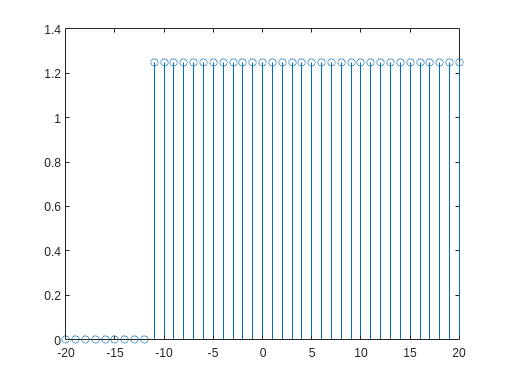

ni = -20;
nf = ni +40;
n0 = -11;
A = 1.25;

[uesc, nesc] = escalon(ni, nf, n0, A);
stem(nesc, uesc);

## Función impulso:

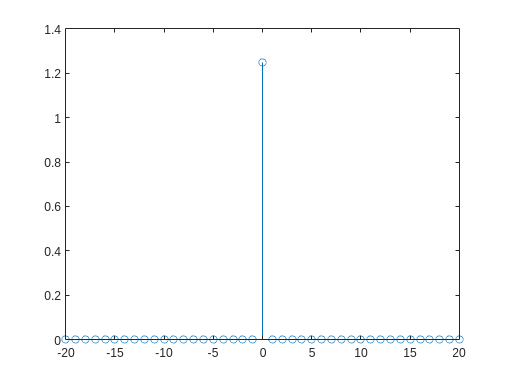

ni = -20;
nf = ni +40;
n0 = 0;
A = 1.25;

[uimp, nimp] = impulso(ni, nf, n0, A);
stem(nimp, uimp);

## Función pulso:

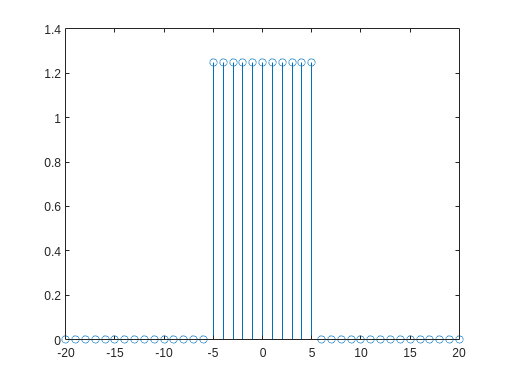

ni = -20;
nf = ni +40;
n0 = -5;
n1 = n0 +10;
A = 1.25;

[upul, npul] = pulso(ni, nf, n0, n1, A);
stem(npul, upul);

## Función rampa:

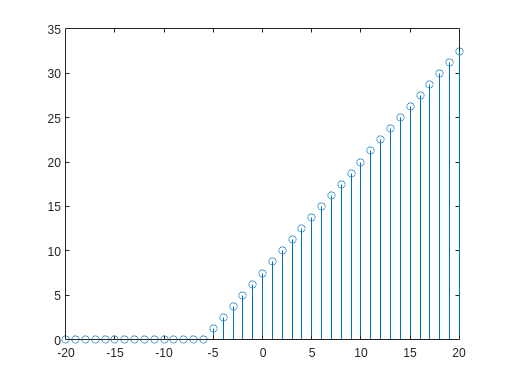

ni = -20;
nf = ni +40;
n0 = -6;
m = 1.25;

[uram, nram] = rampa(ni, nf, n0, m);
stem(nram, uram);

## Función seno cardinal:

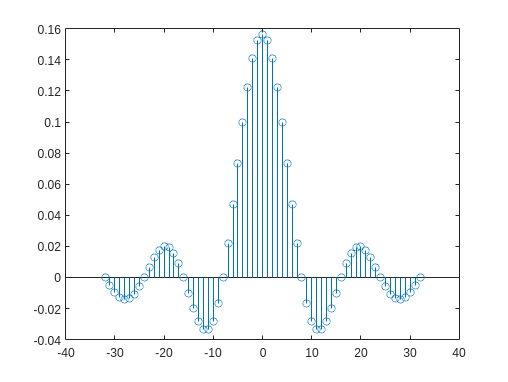

N = 8;
p = 4;
A = 1.25;

[usen, nsen] = senoc(N, p, A);
stem(nsen, usen);

## Función triangular:

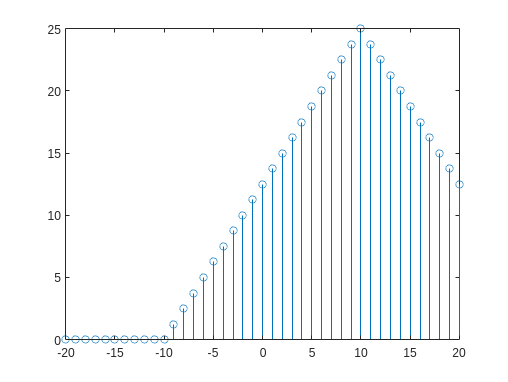

ni = -20;
nf = ni +40;
n0 = -10;
n1 = n0 +40;
m = 1.65;

[utri, ntri] = triangular(ni, nf, n0, n1, A);
stem(ntri, utri);

# b) Operaciones sobre señales discretas

## Desplazamiento:

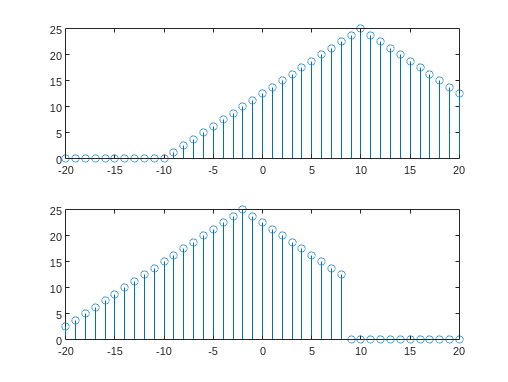

a = -12;

[udes, ndes] = desplazamiento(utri, find(ntri==0), a);
figure();
subplot(2,1,1);stem(ntri, utri);
subplot(2,1,2);stem(ndes, udes);

## Compresión:

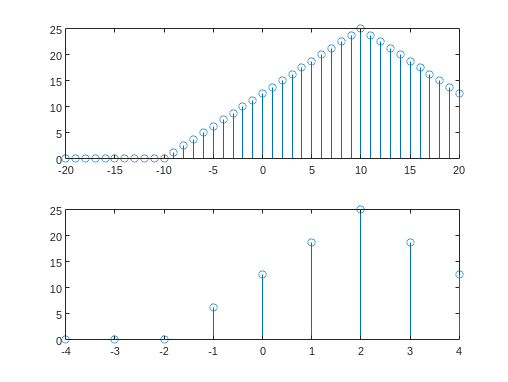

a = 5;

[udes, ndes] = compresion(utri, find(ntri==0), a);
figure();
subplot(2,1,1);stem(ntri, utri);
subplot(2,1,2);stem(ndes, udes);

## Dilatación:

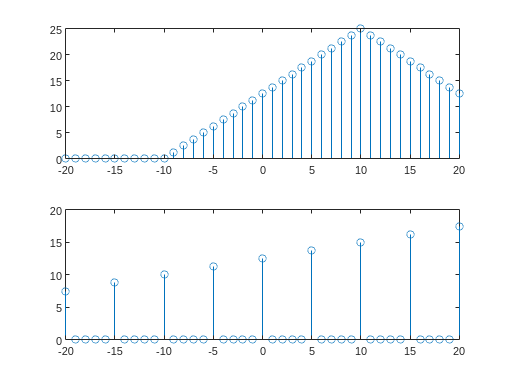

a = 5;

[udes, ndes] = dilatacion(utri, find(ntri==0), a);
figure();
subplot(2,1,1);stem(ntri, utri);
subplot(2,1,2);stem(ndes, udes);

## Reflexión:

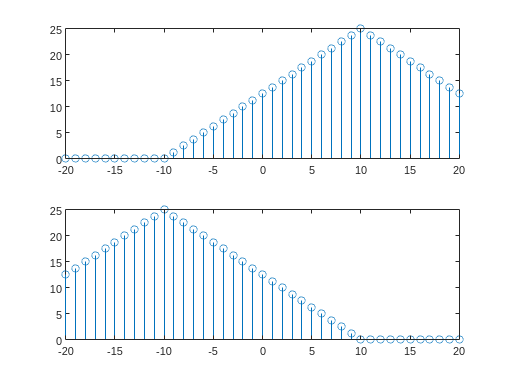

[udes, ndes] = reflexion(utri, find(ntri==0));
figure();
subplot(2,1,1);stem(ntri, utri);
subplot(2,1,2);stem(ndes, udes);

# c) Trenes de ondas

## Señal senoidal rectificada de onda completa

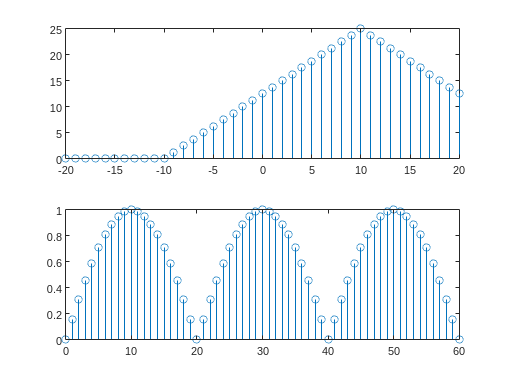

A = 1;
w = 20;
n = 3;

[usen_rec, nsen_rec] = rectificadacompleta(A, w, n);
stem(nsen_rec, usen_rec);

# d) Convolución

Se muestra un pequeño ejemplo de cómo afecta aplicar la convolución de una señal con un impulso retrasado. 

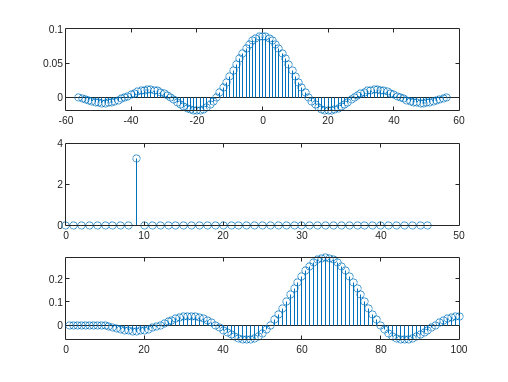

% SEÑAL X
N = 14;
p = 4;
A = 1.25;
[val_x, n_x] = senoc(N, p, A);

% SEÑAL H
nf = 46;
n0 = 9;
A = 3.25;
[val_h, n_h] = impulso(0, nf, n0, A);

% CALCULO CONVOLUCION
n_conv = 1:100;
val_conv = convolucion(val_x, val_h, 1, length(n_conv));

% REPRESENTACION
figure();
subplot(3,1,1);stem(n_x, val_x);
subplot(3,1,2);stem(n_h, val_h);
subplot(3,1,3);stem(n_conv, val_conv);